# Question-2

%% --- Defining matrices from homework-2 --- %%
clc;
clear;

%% Governing equations 
% States: 
% x1 = β  -  % sideslip angle 
% x2 = r  -  % yaw angular velocity 
% x3 = ρ  -  % roll angular velocity 
% x4 = φ  -  % roll angle 
% x5 = ψ  -  % yaw angle 

%% Control inputs: 
% u1 = delr  -  % rudder deflection 
% u2 = dela  -  % aileron deflection

% System matrix A
A = [-0.0297 -1.0000 0 0.0438 0;
      0.3310 -0.0042 -0.0461 0 0;
     -1.1349 0.1286 -0.7949 0 0;
      0 0 1.0000 0 0;
      0 1.0000 0 0 0;];

% Input matrix B
B = [0 0;
     0.3807 0.0671;
     0.0404 1.5871;
     0 0;
     0 0;];

% States weights matrix `Q`
Q = [1 0 0 0 1;
     0 0 0 0 0;
     0 0 0 0 0;
     0 0 0 1 0;      
     1 0 0 0 1];

% Input penalty matrix `R'
R = [1 0;     
     0 1];

% Output matrix 'C'
C = eye(size(A,1));

% feedforward matrix 'D'
D = zeros([size(A,1),2]);

% States weights matrix `P`
P = zeros(size(A,1),size(A,1));

% Number of states 'n', and control inputs 'p'
n = size(A,1); %number of states
m = size(B,2); %number of control inputs
p = size(C,1); %number of outputs

% Sampling time
t = 0.1;
sys = ss(A,B,C,D);

% Discretizing the system with sampling time of 0.1 seconds
[sysd]=c2d(sys,t);

% Discretized system matrices
A = sysd.A

A =     0.9954   -0.0998    0.0004    0.0044         0
    0.0333    0.9979   -0.0044    0.0001         0
   -0.1087    0.0179    0.9235   -0.0002         0
   -0.0055    0.0008    0.0961    1.0000         0
    0.0017    0.0999   -0.0002    0.0000    1.0000


B = sysd.B

B =    -0.0019   -0.0003
    0.0380    0.0063
    0.0042    0.1526
    0.0002    0.0077
    0.0019    0.0003


C = sysd.C

C =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


D = sysd.D

D =      0     0
     0     0
     0     0
     0     0
     0     0


### (a) Checking if the discrete-time open-loop system is asymptotically stable -  

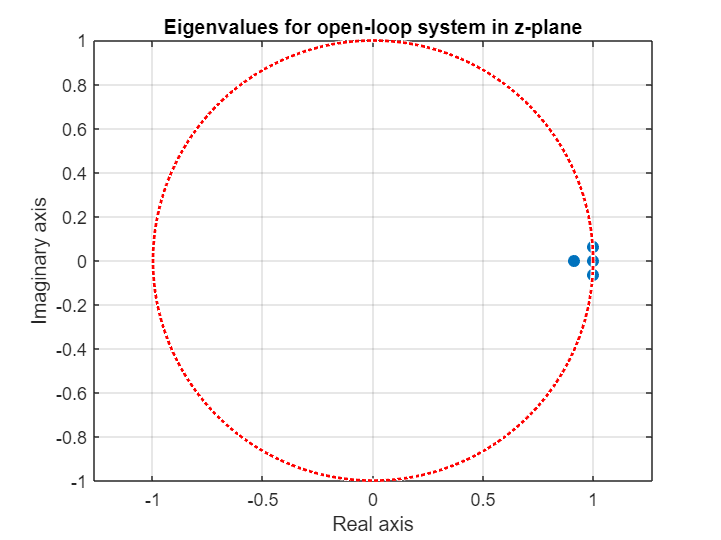

% Eigen values of system matrix 'Ad'
e = eig(A);

% Plotting eigen values and a unit circle
figure
plot(real(e),imag(e),'.','MarkerSize',20)
axis equal
hold on
viscircles([0,0], 1, 'LineStyle',':', 'Color', 'red','Linewidth', 1.5);
title('Eigenvalues for open-loop system in z-plane')
xlabel('Real axis')
ylabel('Imaginary axis')
grid
hold off


% Checking stability 
if any(abs(e) >= 1,'all') 
    fprintf('System is asymptotically unstable.');
else
    fprintf('System is asymptotically stable.');
end

System is asymptotically unstable.

disp('Absolute value of Eigenvalues -') 

Absolute value of Eigenvalues -


abs(e)

ans =     1.0000
    0.9152
    1.0026
    1.0026
    1.0005


### (b) Increasing prediction horizon length from 1 (until 10) to find the gain which results in a stable system -

warning('off','all')

N=0;
stability = 0;

% Loop to increament `N` until stabilizing gain is found 
while stability ~= 1 && N<10
    N = N+1;
    for t = 1:800
        if t==1
            x = [0; 0.1; 0.2; 0; 0]; % initial states
        else
            x=x; 
        end
        [G,F] = mpcsolver(A,B,C,Q,P,R,n,m,p,N,[],[],[],[]);
        U = quadprog(G,F*x);
        K = inv(G)*F;
        Umpc(t,:) = U(1:m,1)';
        Kmpc = K(1:m,:); % input gains
    end
        eig_m = abs(eig(A-B*Kmpc)); % absolute eigenvalues matrix
        stability = 1; 
    if any(eig_m > 1) 
        stability = 0;
    end
    system(N).prediction_horizon = N; %storing prediction horizons
    system(N).stable = stability; %storing corresponding stability values
    system(N).gain = Kmpc; %storing corresponding gains
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

#### Prediction horizon length which results in a stable system - 

fprintf('System is stable when Prediction horizon length = %d.', system(N).prediction_horizon)

System is stable when Prediction horizon length = 8.

fprintf('Eigenvalues lie in the unit circle, hence stability = %d.', system(N).stable)

Eigenvalues lie in the unit circle, hence stability = 1.

% fprintf('Stabilizing gains = %d', system(N).gain)
disp('Stabilizing gain matrix - ')

Stabilizing gain matrix - 


fprintf('%d %d %d %d %d\n', system(N).gain')

-2.515588e-03 1.320019e-03 9.173468e-03 1.914067e-02 1.138888e-03
-6.003129e-02 2.280756e-02 1.741274e-01 3.905523e-01 4.934918e-03


disp('Prediction horizon and Stability during iterations - ')

Prediction horizon and Stability during iterations - 


system

system = 1×8 struct array with fields:
    prediction_horizon
    stable
    gain


### (c) Plotting time history of all states and input when (N=10) and finding the maximum values of rudder and aileron angles -

#### Solving the problem for 'N = 10' -  

clearvars -except A B C D Q P R n m p;

% When N=10
N=10;
warning('off','all')

for t = 1:2000
    if t==1
        x = [0; 0.1; 0.2; 0; 0];
    else
        x=x;
    end
    [G,F] = mpcsolver(A,B,C,Q,P,R,n,m,p,N,[],[],[],[]);
    U = quadprog(G,F*x);
    Umpc(t,:) = U(1:m,1)';
    x = A*x+B*(Umpc(t,:)');
    xMPC(t,:) = x';
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

#### Maximum values of rudder and aileron angles - 

delr_max = max(Umpc(:,1));
dela_max = max(Umpc(:,2));
fprintf('Maximum value of rudder angle = %d.', delr_max);

Maximum value of rudder angle = 4.680803e-03.

fprintf('Maximum value of aileron angle = %d.', dela_max);

Maximum value of aileron angle = 7.661365e-02.

#### Plotting the time history of all states and inputs -

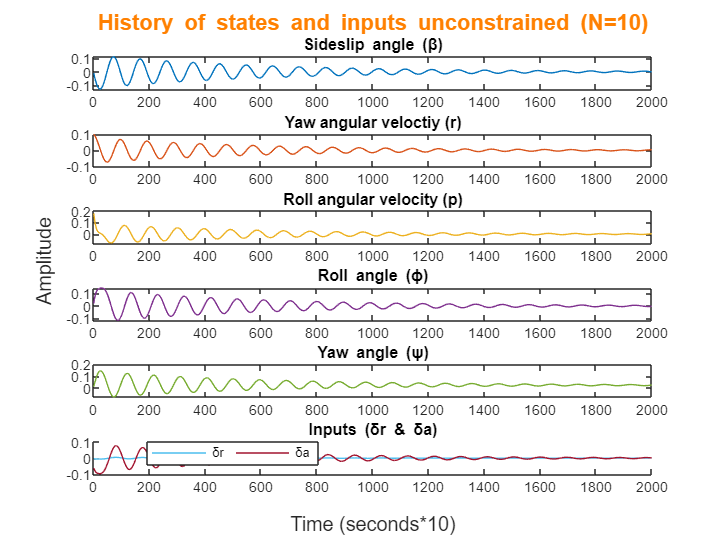

% figure
fig1 = figure;

% Sideslip angle
subplot(6,1,1);
plot(xMPC(:,1),'Color',[0, 0.4470, 0.7410])
title('Sideslip angle (\beta)')
% Yaw angle
subplot(6,1,2);
plot(xMPC(:,2),'Color',[0.8500, 0.3250, 0.0980])
title('Yaw angular veloctiy (r)')
% Yaw angular veloctiy
subplot(6,1,3);
plot(xMPC(:,3),'Color',[0.9290, 0.6940, 0.1250])
title('Roll angular velocity (p)')
% Roll angle
subplot(6,1,4);
plot(xMPC(:,4),'Color',[0.4940, 0.1840, 0.5560])
title('Roll angle (\phi)')
% Roll angular velocity 
subplot(6,1,5);
plot(xMPC(:,5),'Color',[0.4660, 0.6740, 0.1880])
title('Yaw angle (\psi)')
% Inputs 
subplot(6,1,6);
hold on 
plot(Umpc(:,1),'Color',[0.3010 0.7450 0.9330])
plot(Umpc(:,2),'Color',[0.6350 0.0780 0.1840])
legend('\deltar','\deltaa', Location='best', Orientation='horizontal')
hold off
title('Inputs (\deltar & \deltaa)')

f1=axes(fig1,'visible','off'); 
f1.Title.Visible='on';
f1.XLabel.Visible='on';
f1.YLabel.Visible='on';
ylabel(f1,'Amplitude');
xlabel(f1,'Time (seconds*10)');
title(f1,'\color{orange}History of states and inputs unconstrained (N=10)','FontSize',12);

### (d) Constraints on the input -

#### Control inputs are bounded to 50% of their maximum values -

clearvars -except A B C D Q P R n m p delr_max dela_max;

umin = [-0.5*delr_max; -0.5*dela_max];
umax = [0.5*delr_max; 0.5*dela_max ];

#### Solving the problem for N = 10 - 

warning('off','all')

N = 10;
for t = 1:2000
    if t==1
        x = [0; 0.1; 0.2; 0; 0];
    else
        x=x;
    end

    [G,F,S,Cc,W] = mpcsolver(A,B,C,Q,P,R,n,m,p,N,umax,umin,[],[]);
    U = quadprog(G,F*x,S,Cc+W*x);
    Umpc(t,:) = U(1:m,1)';
    K = inv(G)*F; 
    Kmpc = K(1:m,:); % input gains
    x = A*x+B*(Umpc(t,:)');
    xMPC(t,:) = x';
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

#### Plotting the time history of all states and inputs -

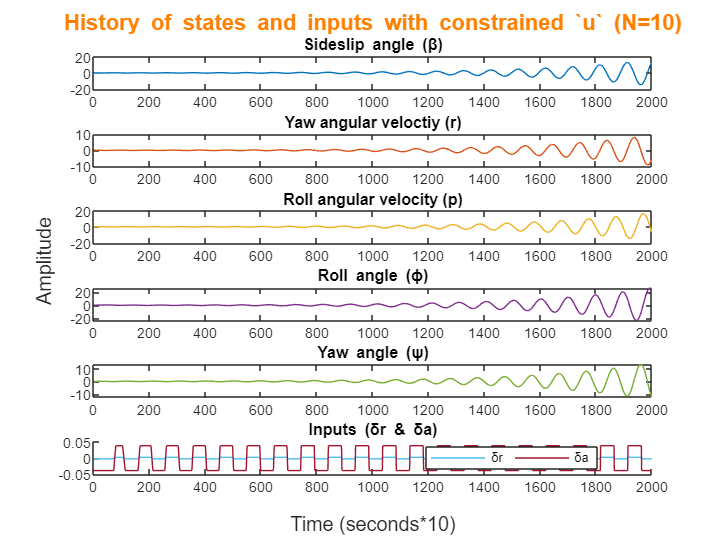

% figure
clf
fig2 = figure;
% Sideslip angle
subplot(6,1,1);
plot(xMPC(:,1),'Color',[0, 0.4470, 0.7410])
title('Sideslip angle (\beta)')
% Yaw angle
subplot(6,1,2);
plot(xMPC(:,2),'Color',[0.8500, 0.3250, 0.0980])
title('Yaw angular veloctiy (r)')
% Yaw angular veloctiy
subplot(6,1,3);
plot(xMPC(:,3),'Color',[0.9290, 0.6940, 0.1250])
title('Roll angular velocity (p)')
% Roll angle
subplot(6,1,4);
plot(xMPC(:,4),'Color',[0.4940, 0.1840, 0.5560])
title('Roll angle (\phi)')
% Roll angular velocity 
subplot(6,1,5);
plot(xMPC(:,5),'Color',[0.4660, 0.6740, 0.1880])
title('Yaw angle (\psi)')
% Inputs 
subplot(6,1,6);
hold on 
plot(Umpc(:,1),'Color',[0.3010 0.7450 0.9330])
plot(Umpc(:,2),'Color',[0.6350 0.0780 0.1840])
legend('\deltar','\deltaa', Location='best', Orientation='horizontal')
hold off
title('Inputs (\deltar & \deltaa)')

f2=axes(fig2,'visible','off'); 
f2.Title.Visible='on';
f2.XLabel.Visible='on';
f2.YLabel.Visible='on';
ylabel(f2,'Amplitude');
xlabel(f2,'Time (seconds*10)');
title(f2,'\color{orange}History of states and inputs with constrained `u` (N=10)','FontSize',12)

As seen from the graph, the system looks unstable for `N=10 when control input is applied for 200 seconds.  Hence, the prediction horizon is increased to 100.  `

#### Increasing the prediction horizon and solving the problem for N = 100 - 

clearvars -except A B C D Q P R n m p delr_max dela_max;
warning('off','all')

umin = [-0.5*delr_max; -0.5*dela_max];
umax = [0.5*delr_max; 0.5*dela_max ];

N = 100;
for t = 1:2000
    if t==1
        x = [0; 0.1; 0.2; 0; 0];
    else
        x=x;
    end

    [G,F,S,Cc,W] = mpcsolver(A,B,C,Q,P,R,n,m,p,N,umax,umin,[],[]);
    U = quadprog(G,F*x,S,Cc+W*x);
    Umpc(t,:) = U(1:m,1)';
    K = inv(G)*F; 
    Kmpc = K(1:m,:); % input gains
    x = A*x+B*(Umpc(t,:)');
    xMPC(t,:) = x';
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

#### Plotting the time history of all states and inputs for N = 100 -

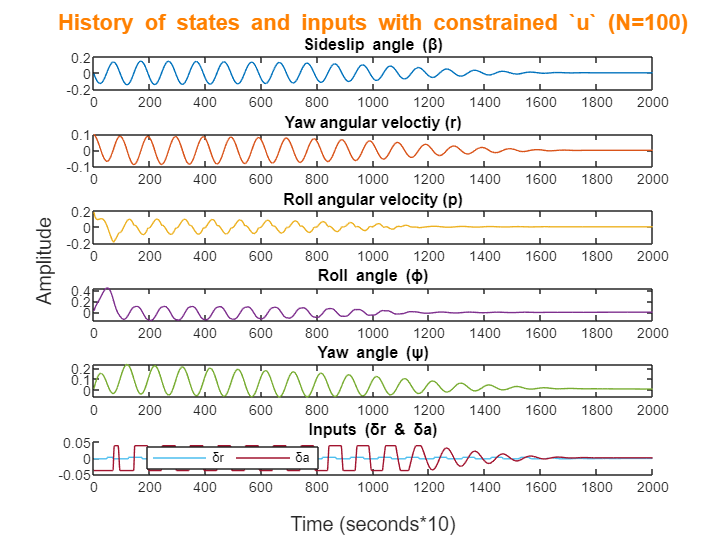

% figure
clf
fig3 = figure;
% Sideslip angle
subplot(6,1,1);
plot(xMPC(:,1),'Color',[0, 0.4470, 0.7410])
title('Sideslip angle (\beta)')
% Yaw angle
subplot(6,1,2);
plot(xMPC(:,2),'Color',[0.8500, 0.3250, 0.0980])
title('Yaw angular veloctiy (r)')
% Yaw angular veloctiy
subplot(6,1,3);
plot(xMPC(:,3),'Color',[0.9290, 0.6940, 0.1250])
title('Roll angular velocity (p)')
% Roll angle
subplot(6,1,4);
plot(xMPC(:,4),'Color',[0.4940, 0.1840, 0.5560])
title('Roll angle (\phi)')
% Roll angular velocity 
subplot(6,1,5);
plot(xMPC(:,5),'Color',[0.4660, 0.6740, 0.1880])
title('Yaw angle (\psi)')
% Inputs 
subplot(6,1,6);
hold on 
plot(Umpc(:,1),'Color',[0.3010 0.7450 0.9330])
plot(Umpc(:,2),'Color',[0.6350 0.0780 0.1840])
legend('\deltar','\deltaa', Location='best', Orientation='horizontal')
hold off
title('Inputs (\deltar & \deltaa)')

f3=axes(fig3,'visible','off'); 
f3.Title.Visible='on';
f3.XLabel.Visible='on';
f3.YLabel.Visible='on';
ylabel(f3,'Amplitude');
xlabel(f3,'Time (seconds*10)');
title(f3,'\color{orange}History of states and inputs with constrained `u` (N=100)','FontSize',12)

#### Checking if the system is stable when 'N = 100' - 

e = eig(A-B*Kmpc);
if any(abs(e) >= 1, 'all') 
    fprintf('System is unstable, when N = %d.', N);
else
    fprintf('System is stable, when N = %d.', N);
end

System is stable, when N = 100.

disp('Absolute value of Eigenvalues -') 

Absolute value of Eigenvalues -


abs(e)

ans =     0.9061
    0.9061
    0.9980
    0.9820
    0.9820


### (e) Constraints on 'Yaw Angle (Ψ)' -

#### Minimum and maximum constraints - 

clearvars -except A B D Q P R n m p

ymin = [0; 0; 0; 0; -0.08];
ymax = [0; 0; 0; 0; 0.08];

#### Solving the problem for N = 10 - 

warning('off','all')
N = 10;
C =  [0 0 0 0 0;
      0 0 0 0 0;
      0 0 0 0 0;
      0 0 0 0 0;
      0 0 0 0 1;];

% Estimating states for N=10
for t = 1:2000
    if t==1
        x = [0; 0.1; 0.2; 0; 0];
    else
        x=x;
    end 
    [G,F,S,Cc,W] = mpcsolver(A,B,C,Q,P,R,n,m,p,N,[],[],ymax,ymin);
    U = quadprog(G,F*x,S,Cc+W*x);
    Umpc(t,:) = U(1:m,1)';
    K = inv(G)*F;
    Kmpc = K(1:m,:); % input gains
    x = A*x+B*(Umpc(t,:)');
    xMPC(t,:) = x';
    yMPC(t,:) = (C*x)';
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Kmpc =    -0.0069    0.0039    0.0183    0.0323    0.0022
   -0.1200    0.0527    0.2808    0.5449    0.0088



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Kmpc =    -0.0069    0.0039    0.0183    0.0323    0.0022
   -0.1200    0.0527    0.2808    0.5449    0.0088



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Kmpc =    -0.0069    0.0039    0.0183    0.0323    0.0022
   -0.1200    0.0527    0.2808    0.5449    0.0088



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Kmpc =    -0.0069    0.0039    0.0183    0.0323    0.0022
   -0.1200    0.0527    0.2808    0.5449    0.0088



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Kmpc =    -0.0069    0.0039    0.0183    0.0323    0.0022
   -0.1200    0.0527    0.2808    0.5449    0.0088



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Kmpc =    -0.0069    0.0039    0.0183    0.0323    0.0022
   -0.1200    0.0527    0.2808    0.5449    0.0088



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Kmpc =    -0.0069    0.0039    0.0183    0.0323    0.0022
   -0.1200    0.0527    0.2808    0.5449    0.0088



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Kmpc =    -0.0069    0.0039    0.0183    0.0323    0.0022
   -0.1200    0.0527    0.2808    0.5449    0.0088



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Kmpc =    -0.0069    0.0039    0.0183    0.0323    0.0022
   -0.1200    0.0527    0.2808    0.5449    0.0088



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Kmpc =    -0.0069    0.0039    0.0183    0.0323    0.0022
   -0.1200    0.0527    0.2808    0.5449    0.0088


#### Checking if the system is stable when 'N = 10' - 

e = eig(A-B*Kmpc);
if any(abs(e) >= 1, 'all') 
    fprintf('System is unstable, when N = %d.', N);
else
    fprintf('System is stable, when N = %d.', N);
end

System is stable, when N = 10.

disp('Absolute value of Eigenvalues -') 

Absolute value of Eigenvalues -


abs(e)

ans =     0.9404
    0.9404
    0.9983
    0.9983
    0.9999


#### Plotting the time history of all states and inputs -

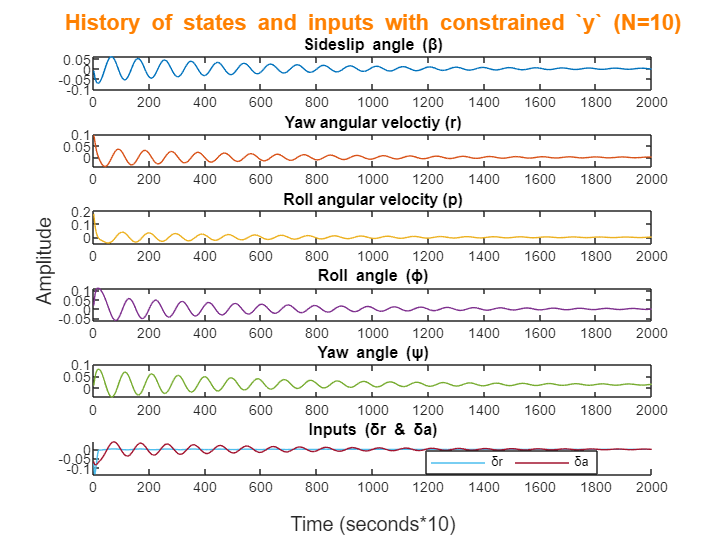

% figure
clf
fig4 = figure;
% Sideslip angle
subplot(6,1,1);
plot(xMPC(:,1),'Color',[0, 0.4470, 0.7410])
title('Sideslip angle (\beta)')
% Yaw angle
subplot(6,1,2);
plot(xMPC(:,2),'Color',[0.8500, 0.3250, 0.0980])
title('Yaw angular veloctiy (r)')
% Yaw angular veloctiy
subplot(6,1,3);
plot(xMPC(:,3),'Color',[0.9290, 0.6940, 0.1250])
title('Roll angular velocity (p)')
% Roll angle
subplot(6,1,4);
plot(xMPC(:,4),'Color',[0.4940, 0.1840, 0.5560])
title('Roll angle (\phi)')
% Roll angular velocity 
subplot(6,1,5);
plot(xMPC(:,5),'Color',[0.4660, 0.6740, 0.1880])
title('Yaw angle (\psi)')
% Inputs 
subplot(6,1,6);
hold on 
plot(Umpc(:,1),'Color',[0.3010 0.7450 0.9330])
plot(Umpc(:,2),'Color',[0.6350 0.0780 0.1840])
legend('\deltar','\deltaa', Location='best', Orientation='horizontal')
hold off
title('Inputs (\deltar & \deltaa)')

f4=axes(fig4,'visible','off'); 
f4.Title.Visible='on';
f4.XLabel.Visible='on';
f4.YLabel.Visible='on';
ylabel(f4,'Amplitude');
xlabel(f4,'Time (seconds*10)');
title(f4,'\color{orange}History of states and inputs with constrained `y` (N=10)','FontSize',12)